# Secant Method

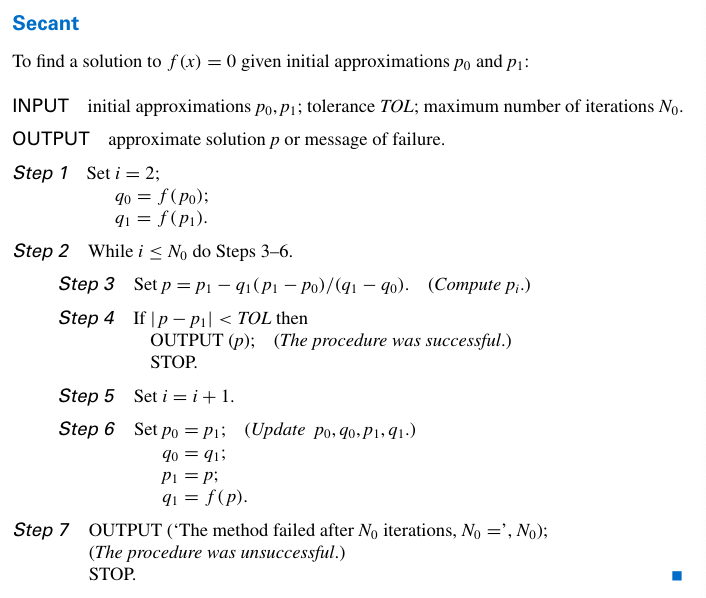

## Initialization

clc;
clear;
close all; %Clear before

## Add initial condition

tol = 1.e-5;           % Tolorence of result
nmax = 100;             % Maximum number of iterations
p_0 = 0.5;              % Initial Prediction value P_0
p_1 = pi/3;             % Initial Prediction value P_1
xmin = 0;               % min x of plot interval
xmax = pi/2;            % max x of plot interval
itcount = 1;            % Number of initialization iterations, here start with i=2
error = 10000;          % Error initialization

## Plot the fraph

About the drawing related parameters, and start the graphic diagram to draw simple pictures


xval = linspace(xmin,xmax,100); 
for i=1:100
    fval(i) = func(xval(i));        %Calculate function image points
end
plot(xval,fval);                    %Plot the function

Start point calculation:

grid on;
hold on;
while (itcount <= nmax && error >=tol)                      %When the number of iterations does not overflow, the error is still too large
    itcount =itcount+1;
    p = p_1-func(p_1)*(p_1-p_0)/(func(p_1)-func(p_0));      %Iteration function of the Secant's Method
    z(itcount) = p;                                         %Record the result into the dataset
    error = abs(p-p_1);                                     %Calculate the error
    if (error < tol)                                        %Campare the result 
        p_final = p;                                        %If the result is acceptable then record it as the final result
    else
        p_0 = p_1;                                          %Set the result as the initial value for nex iteration
        p_1 = p;
    end
end

Plot the Graph 绘制图像

plot(z(1:itcount),zeros(itcount,1),'rx'); % Plot the point with the dataset

if (itcount <nmax)
    val = func(p);
    fprintf('Converged solution after %d iterations',itcount);
    fprintf(' is %.7e\n',p_final);
else
    fprinf('Not converged after %5d iterations',namx);
end

Converged solution after 5 iterations

 is 7.3908513e-01


## Appendix: Function

Here is an Example of the function

function val = func(x)
    val = cos(x)-x;
end